# Tuning ottimale controllore PID - joint2

### Caricamento modelli dei processi

clear all; clc; close all

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

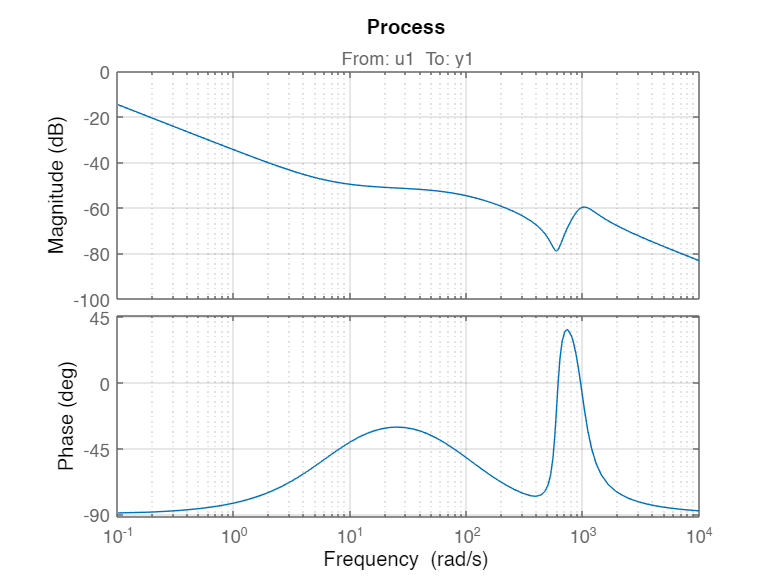

load modello_j2.mat

process = modello_continuo_tf_j2;
figure
bodeplot(process)
grid on; title('Process');

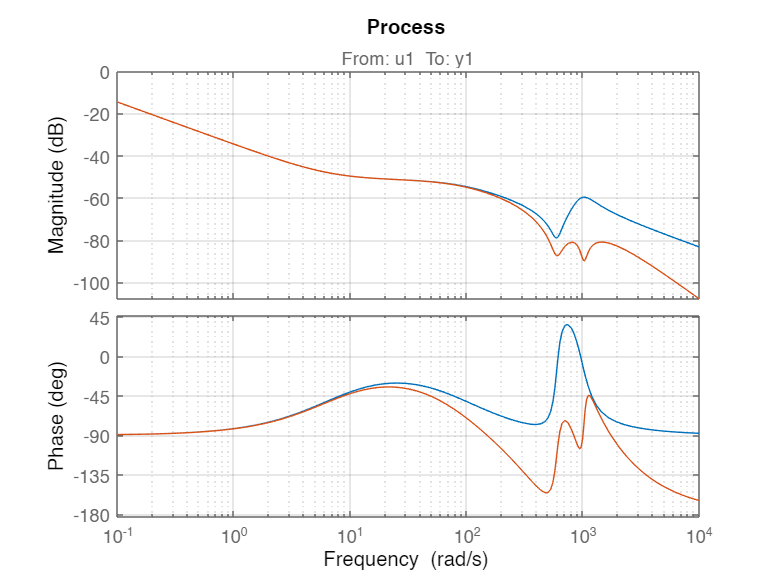

s=tf('s');
w_f=600;
[gpeak,fpeak] = getPeakGain(process*10^(64/20),[],[800 2000]); % constraint of the frequencies personalize for our system
if(gpeak > 1/10)
    notch_filter=notch(fpeak,1/10/gpeak);
else
    notch_filter=1;
end
process_notch = process * notch_filter;
filter = 1/(s/w_f+1)^1;

figure
bode(process,process_notch*filter)
grid on; title('Process');

total_process = minreal(process_notch * filter);
tot_filter = filter * notch_filter;


Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

#### Inner loop: output Filtered **P **


$$C_2(s)=K_p \cdot \frac{1}{T_{fu}s+1}$$


Cifra di merito da minimizzare:


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint2.wc_des = 300;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x, 0, 0, 0, 0],total_process,internal_joint2.wc_des,0);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
internal_joint2.MS = 1.5;

% Reiezione disturbo di misura
internal_joint2.wh = 2000;
internal_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint2.wl = 10;
internal_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint2.PM_min = 65;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint2.wl;internal_joint2.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints([x, 0, 0, 0, 0], total_process, w_vector, ...
                                 internal_joint2.MS, internal_joint2.wh, internal_joint2.Fh_max, ...
                                 internal_joint2.wl, internal_joint2.Dl_max, internal_joint2.PM_min,0);

### Ottimizzatore interno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
internal_joint2.aKp = [1400, 100, 10000];
%internal_joint2.aKi = [0, 0, 0];
%internal_joint2.aKd = [0, 0, 0];
%internal_joint2.aTfd = [0, 0, 0];
%internal_joint2.aTfu = [1/300, 1/500, 1/40];

x0 = [internal_joint2.aKp(1)];

problem = createOptimProblem('fmincon','x0',x0,  'objective',J, 'lb',[internal_joint2.aKp(2)],  'ub', [internal_joint2.aKp(3)],  'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       14        4164                                    4164            1    Initial Point
     200     1230        4164                                    4164            1    Stage 1 Local
     300     1332        4164     4.955e+04         8636                              Stage 2 Search
     361     1411        4164     1.485e+04    1.492e+04         4164            1    Stage 2 Local
     362     1430        4164     1.484e+04    1.485e+04         4164            1    Stage 2 Local
     363     1449        4164     1.451e+04    1.484e+04         4164            1    Stage 2 Local
     364     1468        4164     1.426e+04    1.451e+04         4164            1    Stage 2 Local
     365     1487        4164     1.415e+04    1.426e+04         4164            1    Stage 2 Local

x = 1.2978e+03

nlcon(x)

ans =    -0.0177   -0.0992   -0.0811   -0.0000


s=tf('s');
Kp = x(1);
Cv_joint2 = tf(Kp);
Cv_joint2.InputName = 'sp-vel';
Cv_joint2.OutputName = 'torque';

Loop_int_joint2 = total_process*Cv_joint2;

figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 1.4270

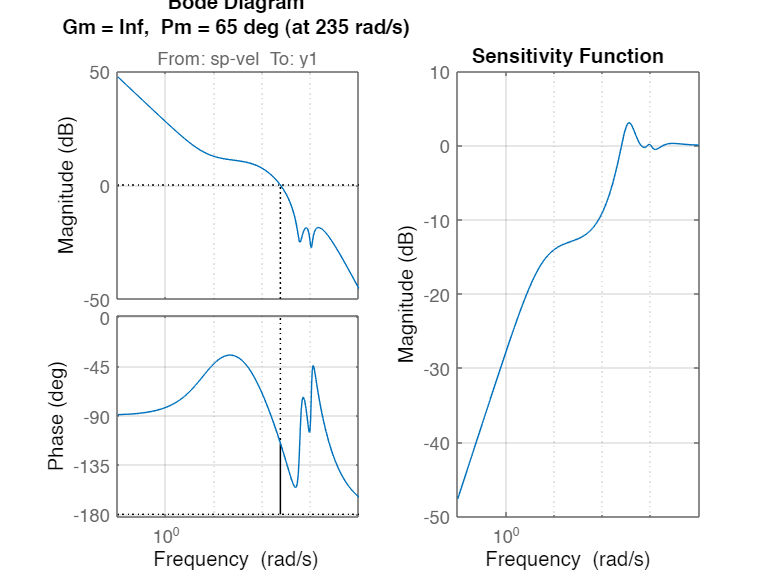

grid on

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\textrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


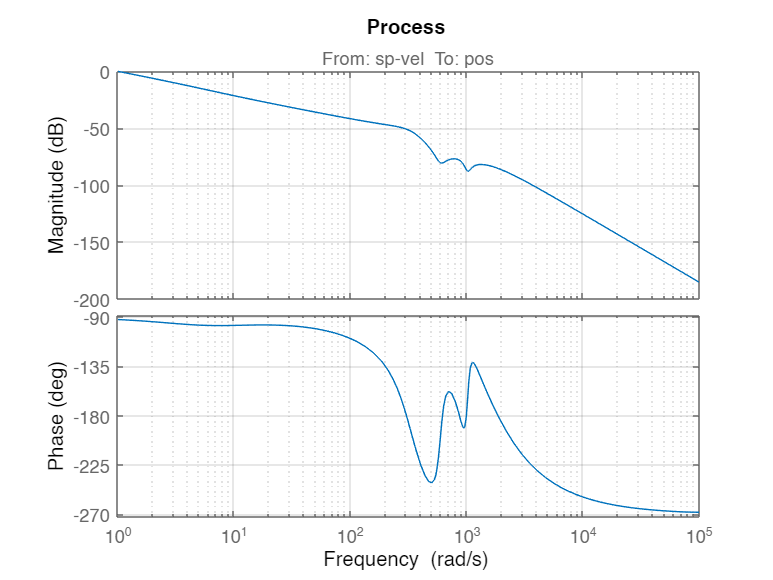

process_ext = minreal(feedback(Loop_int_joint2,1)*1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';
figure
bodeplot(process_ext)
grid on; title('Process');

external_joint2.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x(1), x(2), 0, 0, 0],process_ext,external_joint2.wc_des,0);

### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint2.MS = 1.5;

% Reiezione disturbo di misura
external_joint2.wh = 2000;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 10;
external_joint2.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 75;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint2.wl;external_joint2.wh]));

nlcon = @(x)pid_filt_constraints([x(1), x(2), 0, 0, 0], process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dl_max, external_joint2.PM_min,0);

### Ottimizzatore esterno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint2.aKp = [120, 0.01, 2000];
external_joint2.aKi = [1/200, 1/1000, 100];
%external_joint2.aKd = [0, 0, 0];
%external_joint2.aTfd = [0, 0, 0];
%external_joint2.aTfu = [0, 0, 0];

x0 = [external_joint2.aKp(1), external_joint2.aKi(1)];

opt1=optimoptions("ga","MaxTime",3600*0.1,'InitialPopulation',x0,'Display','iter');

x1=ga(J,2,[],[],[],[],[external_joint2.aKp(2), external_joint2.aKi(2)] ...
    ,[external_joint2.aKp(3), external_joint2.aKi(3)] ...
    ,nlcon,opt1);


Single objective optimization:
2 Variable(s)
4 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2520       15407.2     0.000577      0
    2           4982         15408    3.079e-05      0
    3           5458       15407.1    0.0006701      0
Optimization terminated: time limit exceeded.


nlcon(x1)

ans =    -0.0965   -0.0892   -0.0809    0.0007


s=tf('s');
Kp=x1(1); Ki=x1(2);
Cp_joint2=(Kp+Ki/s);
Cp_joint2.InputName = 'sp-vel';
Cp_joint2.OutputName = 'pos';

Loop_int_joint2 = process_ext*Cp_joint2;

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure;
subplot(1,2,1)
margin(Loop_int_joint2)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint2))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint2))

ans = 1.4298

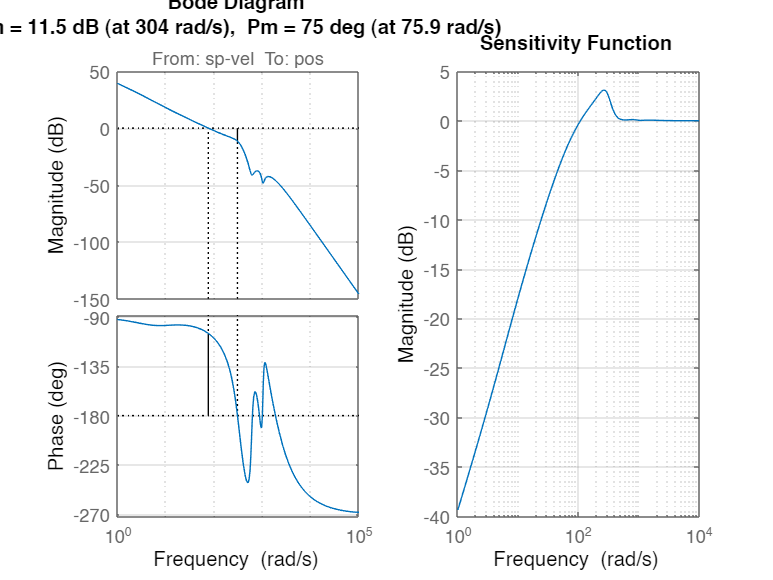

grid on

x = [x, 0, 0, 0, 0];
x1 = [x1, 0, 0, 0];
save("parameters_controller_int_joint2_" +num2str(w_f)+"_"+num2str(internal_joint2.PM_min)+".mat", "x")
save("parameters_controller_ext_joint2_"+num2str(w_f)+"_"+num2str(external_joint2.PM_min)+".mat","x1")
save("tot_filter_joint2_"+num2str(w_f)+"_"+num2str(external_joint2.PM_min)+".mat","tot_filter");